% Input: 
%   data    :   a matrix of size d x N; data points are columns
%   landmarks   :   a matrix of size d x (s+1); landamarks are columns
%   cocycle   :   a matrix of size c x 2; each row is a non-zero edge
clear all 
% close all

use_harmonic = true;

data = 2*rand([3 10000]) - 1;
data = data./(ones([size(data,1) 1])*sqrt(sum(data.^2)));

landmarks = [0 0 1; 2*sqrt(2)/3 0 -1/3; -sqrt(2)/3 sqrt(2/3) -1/3; -sqrt(2)/3 -sqrt(2/3) -1/3]' ;

data = [0 0 1;...
        2*sqrt(2)/3 0 -1/3;...
        -sqrt(2)/3 sqrt(2/3) -1/3;...
        -sqrt(2)/3 -sqrt(2/3) -1/3;...
        1/sqrt(2) 1/sqrt(2) 0;...
        1/sqrt(2) 0 1/sqrt(2);...
        0 1/sqrt(2) 1/sqrt(2);...
        1/sqrt(3) 1/sqrt(3) 1/sqrt(3);...
        -1/sqrt(2) -1/sqrt(2) 0;...
        -1/sqrt(2) 0 -1/sqrt(2);...
        0 -1/sqrt(2) -1/sqrt(2);...
        -1/sqrt(3) -1/sqrt(3) -1/sqrt(3)]' ;


cocycle.simplices = [1 2 3; 1 3 4; 1 2 4; 2 3 4];

% integer_cocycle = [1 1 1 0]';
% integer_cocycle = [1 1 1 1]'; % coboundary
integer_cocycle = [1 0 0 0]'; % fundamental class


delta_1 = [ 1 -1 0 1 0 0; 0 1 -1 0 0 1; 1 0 -1 0 1 0; 0 0 0 1 -1 1];


warning('off', 'MATLAB:rankDeficientMatrix');

if use_harmonic
    nu = delta_1\integer_cocycle; % use harmonic cocycle/solve least squares problem;
else
nu = zeros(size(delta_1,2),1); % use integer coycle
    end
warning('on', 'MATLAB:rankDeficientMatrix');



cocycle.values = integer_cocycle - delta_1*nu; % associated harmonic cocycle

disp(nu)

    0.7500
         0
    0.5000
         0
         0
    0.2500





nu = squareform(nu);

disp(nu)

         0    0.7500         0    0.5000
    0.7500         0         0         0
         0         0         0    0.2500
    0.5000         0    0.2500         0




nu = nu - 2*tril(nu);

disp(nu)

         0    0.7500         0    0.5000
   -0.7500         0         0         0
         0         0         0    0.2500
   -0.5000         0   -0.2500         0




% Output:
%   Mapped data
%   Principal great-nested-spheres analysis

## get dimensions

[d, N] = size(data);
s = size(landmarks,2)-1;
c = size(cocycle.simplices,1);
disp(N)

    12



disp(d)

     3



disp(s)

     3



disp(c)

     4



disp(size(landmarks,2))

     4



## Create the open covering U = {U_1,..., U_{s+1}}

% Compute the distanace matrix between the landmarks

dist_land_land = real(acos(landmarks'*landmarks));

%disp(dist_land_land)

dist_land_land = dist_land_land - diag(diag(dist_land_land));


%disp(diag(dist_land_land))
%disp(diag(diag(dist_land_land)))

% Compute the distance matrix between landmarks and data points

dist_land_data = acos(landmarks'*data);

disp("dist_land_data")

dist_land_data


disp(dist_land_data)

  Columns 1 through 8

   0.0000 + 0.0000i   1.9106 + 0.0000i   1.9106 + 0.0000i   1.9106 + 0.0000i   1.5708 + 0.0000i   0.7854 + 0.0000i   0.7854 + 0.0000i   0.9553 + 0.0000i
   1.9106 + 0.0000i   0.0000 + 0.0000i   1.9106 + 0.0000i   1.9106 + 0.0000i   0.8411 + 0.0000i   1.1252 + 0.0000i   1.8087 + 0.0000i   1.2112 + 0.0000i
   1.9106 + 0.0000i   1.9106 + 0.0000i   0.0000 + 0.0000i   1.9106 + 0.0000i   1.3243 + 0.0000i   2.1761 + 0.0000i   1.2221 + 0.0000i   1.5640 + 0.0000i
   1.9106 + 0.0000i   1.9106 + 0.0000i   1.9106 + 0.0000i   0.0000 + 0.0000i   2.7157 + 0.0000i   2.1761 + 0.0000i   2.5202 + 0.0000i   2.7819 + 0.0000i

  Columns 9 through 12

   1.5708 + 0.0000i   2.3562 + 0.0000i   2.3562 + 0.0000i   2.1863 + 0.0000i
   2.3005 + 0.0000i   2.0164 + 0.0000i   1.3329 + 0.0000i   1.9304 + 0.0000i
   1.8173 + 0.0000i   0.9655 + 0.0000i   1.9195 + 0.0000i   1.5776 + 0.0000i
   0.4259 + 0.0000i   0.9655 + 0.0000i   0.6214 + 0.0000i   0.3596 + 0.0000i




%disp(dist_land_land)
%disp(dist_land_data)

% For each landmark l_j, let r_j be the distance to its nearest landmark

r = sort(dist_land_land,2);
r = r(:,2);
disp(r)

    1.9106
    1.9106
    1.9106
    1.9106




% Let U_j be the set of data points whose distance to l_j is less than r_j
U = (dist_land_data < repmat(r,1,N));

disp("U")

U


disp(U)

   1   0   0   0   1   1   1   1   1   0   0   0
   0   1   0   0   1   1   1   1   0   0   1   0
   0   0   1   0   1   0   1   1   1   1   0   1
   0   0   0   1   0   0   0   0   1   1   1   1



## Optional: Compute the nerve of the covering

n=1; 
edges = cell(nchoosek(s+1,2),3);
for j=1:(s+1)
for k=(j+1):(s+1)
el_edge = find(prod(U([j,k],:)));
edges(n,:) ={[j,k], length(el_edge),el_edge}; 
n = n+1;
end
end

n=1;
triangles = cell(nchoosek(s+1,3),3);
for j=1:(s+1)
for k=(j+1):(s+1)
for l = (k+1):(s+1)
el_trig = find(prod(U([j,k,l],:)));
triangles(n,:) = {[j,k,l], length(el_trig),el_trig};
n = n+1;
end
end
end

n=1;
tetrahedra = cell(nchoosek(s+1,4),3);
for j=1:(s+1)
for k=(j+1):(s+1)
for l = (k+1):(s+1)
for o = (l+1):(s+1)
el_tetra = find(prod(U([j,k,l,o],:)));
tetrahedra(n,:) = {[j,k,l,o], length(el_tetra),el_tetra};
n = n+1;
end
end
end
end

## Compute subordinated partition of unity varphi_1,...,varphi_{s+1}

% Compute the bump phi_j(b) = exp{-r_j^2/(r_j^2 - |b - l_j|^2)} on each
% data point b in U_j. phi_j = 0 outside U_j.

phi = zeros(s+1,N);

for j=1:(s+1)
%      phi(j,U(j,:)) =   max(r(j) - dist_land_data(j, U(j,:)),0);
     phi(j,U(j,:)) =   (r(j) - dist_land_data(j, U(j,:))).^2;
%       phi(j,U(j,:)) =   r(j).^2 - dist_land_data(j, U(j,:)).^2;
%      phi(j,U(j,:)) = exp(r(j)^2./( dist_land_data(j, U(j,:)).^2 - r(j)^2 ));
end

disp("norm of phi")

norm of phi


disp(norm(phi))

    5.2598



disp(size(phi))

     4    12




% Compute the partition varphi_j(b) = phi_j(b)/(phi_1(b) + ... + phi_{s+1}(b))

varphi = phi./(ones(s+1,1)*sum(phi));
disp("varphi")

varphi


disp(varphi)

    1.0000         0         0         0    0.0720    0.6724    0.7233    0.5996    0.0496         0         0         0
         0    1.0000         0         0    0.7135    0.3276    0.0059    0.3214         0         0    0.1673         0
         0         0    1.0000         0    0.2144         0    0.2708    0.0789    0.0037    0.5000         0    0.0441
         0         0         0    1.0000         0         0         0         0    0.9467    0.5000    0.8327    0.9559



disp("norm varphi")

norm varphi


disp(norm(varphi, "fro"))

    3.0366



## To each data point, associate the index of the first open set it belongs to

indx = zeros(1,N);

for j=1:N
    indx(j) = find(U(:,j),1,'first');
end

disp(groupcounts(indx'))

     6
     2
     3
     1



disp(indx)

     1     2     3     4     1     1     1     1     1     3     2     3



## From U_1 to U_{s+1} - (U_1 \cup ... \cup U_s), apply classifying map

% compute representative cocycle theta_{j k l}

theta = zeros([s+1 s+1 s+1]);
disp(size(theta))

     4     4     4




p = perms([1 2 3]);
disp(p)

     3     2     1
     3     1     2
     2     3     1
     2     1     3
     1     3     2
     1     2     3



p = reshape(p',1,[]);
disp(p)

     3     2     1     3     1     2     2     3     1     2     1     3     1     3     2     1     2     3




ind_theta = cocycle.simplices(:,p);

disp(ind_theta)

     3     2     1     3     1     2     2     3     1     2     1     3     1     3     2     1     2     3
     4     3     1     4     1     3     3     4     1     3     1     4     1     4     3     1     3     4
     4     2     1     4     1     2     2     4     1     2     1     4     1     4     2     1     2     4
     4     3     2     4     2     3     3     4     2     3     2     4     2     4     3     2     3     4




%disp(ind_theta)

lin_ind_theta = ind_theta(:,1:3:end) + (s+1)*(ind_theta(:,2:3:end) - 1) + (s+1)^2*(ind_theta(:,3:3:end)-1); 
disp(size(lin_ind_theta))

     4     6



disp(lin_ind_theta)

     7    19    10    34    25    37
    12    36    15    51    45    57
     8    20    14    50    29    53
    28    40    31    55    46    58



lin_ind_theta = reshape(lin_ind_theta,[],1);
disp(lin_ind_theta)

     7
    12
     8
    28
    19
    36
    20
    40
    10
    15
    14
    31
    34
    51
    50
    55
    25
    45
    29
    46
    37
    57
    53
    58




%disp(ind_theta(:,1:3:end))
%disp((ind_theta(:,2:3:end) - 1))
%disp(ind_theta(:,3:3:end)-1)

val_theta = repmat(cocycle.values,1, 6);
disp(val_theta)

    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500
   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500
   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500   -0.2500





disp("shape val_theta")

shape val_theta


disp(size(val_theta))

     4     6



val_theta = sign((ind_theta(:,2:3:end) - ind_theta(:,1:3:end)).*(ind_theta(:,3:3:end) - ind_theta(:,1:3:end)).*(ind_theta(:,3:3:end) - ind_theta(:,2:3:end))).*val_theta;
%val_thape(val_theta,[],1);
disp(val_theta)

   -0.2500    0.2500    0.2500   -0.2500   -0.2500    0.2500
   -0.2500    0.2500    0.2500   -0.2500   -0.2500    0.2500
    0.2500   -0.2500   -0.2500    0.2500    0.2500   -0.2500
    0.2500   -0.2500   -0.2500    0.2500    0.2500   -0.2500



%disp("shape val_theta")
%disp(size(val_theta))
%disp(size(theta(lin_ind_theta)))
%disp(size(theta))

theta(lin_ind_theta) = val_theta;

disp(theta)


(:,:,1) =

         0         0         0         0
         0         0    0.2500   -0.2500
         0   -0.2500         0    0.2500
         0    0.2500   -0.2500         0


(:,:,2) =

         0         0   -0.2500    0.2500
         0         0         0         0
    0.2500         0         0   -0.2500
   -0.2500         0    0.2500         0


(:,:,3) =

         0    0.2500         0   -0.2500
   -0.2500         0         0    0.2500
         0         0         0         0
    0.2500   -0.2500         0         0


(:,:,4) =

         0   -0.2500    0.2500         0
    0.2500         0   -0.2500         0
   -0.2500    0.2500         0         0
         0         0         0         0





% compute all transition functions h_{j k}

h = cell(s+1);

for j=1:(s+1)
    for k=1:(s+1)
        h{j,k} = exp( 2*pi*1i*(reshape(theta(j,k,:),1,[])*varphi + nu(j,k)) );
        disp(norm(h{j,k},"fro"))
    end
end

    3.4641

    3.4641

    3.4641

    3.4641

    3.4641

    3.4641

    3.4641

    3.4641

    3.4641

    3.4641

    3.4641

    3.4641

    3.4641

    3.4641

    3.4641

    3.4641




class_map = sqrt(varphi);
% class_map = varphi./(ones(s+1,1)*sqrt(sum(varphi.^2)));

for j=1:N
   h_k_ind_j = cell2mat(h(:,indx(j)));
%    class_map(:,j) =  class_map(:,j).*h_k_ind_j(:,j);
   class_map(:,j) =  class_map(:,j).*conj(h_k_ind_j(:,j));
end
disp("class map")

class map


disp(class_map)

  Columns 1 through 8

   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.2684 + 0.0000i   0.8200 + 0.0000i   0.8505 + 0.0000i   0.7744 + 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.2792 - 0.7972i  -0.0000 - 0.5724i   0.0318 - 0.0702i   0.0701 - 0.5626i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.2014 - 0.4170i   0.0000 + 0.0000i   0.5204 - 0.0048i   0.2459 - 0.1359i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i

  Columns 9 through 12

   0.2227 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.4090 + 0.0000i   0.0000 + 0.0000i
   0.0051 + 0.0609i   0.7071 + 0.0000i   0.0000 + 0.0000i   0.2099 + 0.0000i
  -0.9730 + 0.0057i   0.0000 + 0.7071i   0.9125 + 0.0000i   0.0000 + 0.9777i



disp(size(class_map))

     4    12





f = zeros([2,1].*size(class_map));
f(1:2:end,:) = real(class_map);
f(2:2:end,:) = imag(class_map);

disp(size(f))

     8    12



disp(size(class_map))

     4    12



disp(norm(class_map,"fro"))

    3.4641



## Run projective dimensionality reduction

addpath(genpath('C:\Users\Jose\Documents\MATLAB\Principal Nested Spheres')) [remat, PNS]= PNSmain(class_map',2); % figure, PNSgraphics(remat,PNS)

% [projData, orthaxis, resmat] = projDimRed(f,1);

X = class_map;
variance = zeros(1,size(X,1)-1);
proj_dim = 1; % dimension of projective space onto which to project.

% % figure
for i=1:(size(class_map,1)-proj_dim-1)

% Last singular vector
[UU, S, ~] = svd(X);
disp("singular vals")
disp(S)
disp("UU")
disp(UU)
%disp("norm UU")
%disp(norm(UU,"fro"))
%disp("norm X")
%disp(norm(X(1),"fro"))
%disp(norm(X(2),"fro"))
%disp(norm(X(3),"fro"))
variance(end+1-i) = mean((pi/2 - real(acos(abs(UU(:,end)'*X))) ).^2) ;
Y = UU'*X;
y = Y(end,:);
disp(y);

% % % Last principal component
% % VV = princomp(X.');
% % XX = VV'*X;
% % x = XX(end,:);
% % 
% % if mean(abs(x).^2) < mean(abs(y).^2) 
% %     Y = XX;
% %     y = x;
% % end

Y(end,:) = [];


% % subplot(2,4,i), hist(abs(Y(1,:)),100), xlim([-0.2 , 1.2])
% subplot(2,4,i+4), hist(abs(y),100), xlim([-0.2 , 1.2])
disp("size division")
%disp(size(sqrt(1 - abs(y).^2)))
%disp(size(ones(size(Y,1),1)*sqrt(1 - abs(y).^2)))
disp(norm(y,"fro"))
X = Y./(ones(size(Y,1),1)*sqrt(1 - abs(y).^2));
disp(X)

% % data_X{i} = X;
% % 
% % distMat = acos(abs(X'*X));
% % distMat = real(distMat);
% % distMat = distMat - diag(diag(distMat));
% % 
% % subplot(2,4,i), hist(squareform(distMat),100)

end

singular vals


    2.1313         0         0         0         0         0         0         0         0         0         0         0
         0    2.0888         0         0         0         0         0         0         0         0         0         0
         0         0    1.3194         0         0         0         0         0         0         0         0         0
         0         0         0    1.1635         0         0         0         0         0         0         0         0



UU


  -0.1028 + 0.0000i  -0.7390 + 0.0000i   0.4717 + 0.0000i   0.4699 + 0.0000i
  -0.0887 - 0.0831i  -0.0922 + 0.5725i  -0.4260 + 0.3689i   0.2633 + 0.5119i
  -0.3325 - 0.0214i  -0.2556 + 0.1463i   0.0596 + 0.6056i  -0.5344 - 0.3826i
   0.0231 - 0.9291i   0.1179 + 0.1304i   0.2904 - 0.0726i  -0.1011 + 0.0747i



  Columns 1 through 8

   0.4699 + 0.0000i   0.2633 - 0.5119i  -0.5344 + 0.3826i  -0.1011 - 0.0747i  -0.1566 - 0.0529i   0.0923 - 0.1507i   0.0958 + 0.1669i   0.0149 - 0.0173i

  Columns 9 through 12

   0.1774 + 0.0415i  -0.3251 + 0.1990i   0.0154 - 0.2775i  -0.0392 - 0.0186i



size division


    1.1635



  Columns 1 through 8

  -0.1164 + 0.0000i  -0.1084 + 0.1016i  -0.4411 + 0.0284i   0.0233 + 0.9365i  -0.0448 + 0.2401i  -0.0373 + 0.0516i  -0.2622 + 0.0220i  -0.1179 + 0.1062i
  -0.8372 + 0.0000i  -0.1127 - 0.7002i  -0.3391 - 0.1941i   0.1188 - 0.1314i  -0.8041 - 0.0094i  -0.9486 + 0.0536i  -0.8206 - 0.0883i  -0.9838 + 0.0105i
   0.5344 + 0.0000i  -0.5210 - 0.4511i   0.0791 - 0.8035i   0.2928 + 0.0731i  -0.5343 + 0.0911i   0.1785 + 0.2477i   0.3973 - 0.3029i   0.0603 + 0.0568i

  Columns 9 through 12

  -0.0546 - 0.9397i  -0.9649 + 0.0340i  -0.0158 + 0.9180i  -0.9791 + 0.0271i
  -0.2755 + 0.1131i  -0.0958 - 0.0217i   0.0727 - 0.3676i   0.0739 + 0.0846i
  -0.1431 - 0.0696i  -0.0099 - 0.2410i   0.0945 - 0.0881i  -0.0585 + 0.1570i



singular vals


    2.2295         0         0         0         0         0         0         0         0         0         0         0
         0    2.1850         0         0         0         0         0         0         0         0         0         0
         0         0    1.5018         0         0         0         0         0         0         0         0         0



UU


   0.8105 + 0.0000i  -0.5803 + 0.0000i  -0.0800 + 0.0000i
   0.3576 + 0.4568i   0.4999 + 0.6423i  -0.0028 - 0.0312i
  -0.0060 + 0.0808i   0.0185 - 0.0218i  -0.1950 + 0.9770i



  Columns 1 through 8

  -0.0925 - 0.5483i  -0.3083 + 0.5873i  -0.7582 + 0.0671i   0.0163 - 0.3711i   0.1993 + 0.4600i   0.2112 - 0.2566i  -0.3474 - 0.3562i   0.0556 - 0.1092i

  Columns 9 through 12

  -0.0385 + 0.2196i  -0.1555 + 0.0510i  -0.0920 - 0.1453i   0.2402 + 0.0264i



size division


    1.5018



  Columns 1 through 8

  -0.4776 + 0.4081i  -0.6432 - 0.0959i  -0.9758 + 0.1649i   0.0059 + 0.6825i  -0.3670 + 0.6947i  -0.3457 + 0.5072i  -0.6607 + 0.3814i  -0.4417 + 0.5380i
  -0.4104 + 0.6610i  -0.5919 - 0.4761i  -0.0296 + 0.1406i  -0.0374 - 0.7299i  -0.4552 + 0.4189i  -0.4456 + 0.6517i  -0.3468 + 0.5456i  -0.4199 + 0.5823i

  Columns 9 through 12

  -0.0984 - 0.5984i  -0.8572 + 0.0667i  -0.1648 + 0.5809i  -0.7373 + 0.0229i
  -0.0355 + 0.7943i   0.5100 + 0.0266i  -0.1897 - 0.7742i   0.6749 - 0.0198i



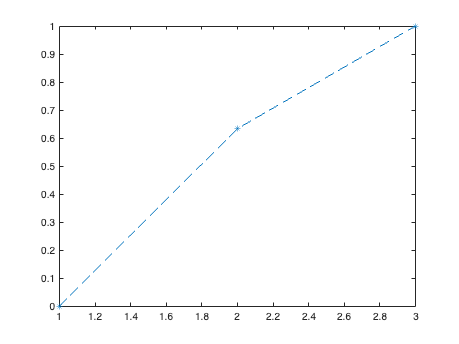


%XX = X;

%for j=1:proj_dim
%    [UU, ~] = svd(XX);
%    disp("norm UU")
%    disp(norm(UU,"fro"))
%    variance(proj_dim-j+1) = mean((pi/2 - real(acos(abs(UU(:,end)'*XX))) ).^2) ;
%    Y = UU'*XX;
%    y = Y(end,:);
%    Y(end,:)= [];
%
%    XX = Y./(ones(size(Y,1),1)*sqrt(1 - abs(y).^2));
%end

variance = cumsum(variance);
variance = variance/variance(end);

figure
plot(variance, '--*')
ylim([0 1])


disp((ones(size(Y,1),1)*sqrt(1 - abs(y).^2)))

    0.8312    0.7483    0.6485    0.9284    0.8653    0.9432    0.8674    0.9925    0.9748    0.9865    0.9851    0.9704
    0.8312    0.7483    0.6485    0.9284    0.8653    0.9432    0.8674    0.9925    0.9748    0.9865    0.9851    0.9704



Z = zeros([2,1].*size(X));
Z(1:2:end,:) = real(X);
Z(2:2:end,:) = imag(X);
projData = Z;
disp(projData)

   -0.4776   -0.6432   -0.9758    0.0059   -0.3670   -0.3457   -0.6607   -0.4417   -0.0984   -0.8572   -0.1648   -0.7373
    0.4081   -0.0959    0.1649    0.6825    0.6947    0.5072    0.3814    0.5380   -0.5984    0.0667    0.5809    0.0229
   -0.4104   -0.5919   -0.0296   -0.0374   -0.4552   -0.4456   -0.3468   -0.4199   -0.0355    0.5100   -0.1897    0.6749
    0.6610   -0.4761    0.1406   -0.7299    0.4189    0.6517    0.5456    0.5823    0.7943    0.0266   -0.7742   -0.0198



## Apply Hopf map to projected data

%projData = [[1 2 3]; [2 3 4]; [5 6 7]; [8 9 10]]

hopf_map = [2*(prod(projData([1 3],:)) + prod(projData([2 4],:)));...
    2*(prod(projData([2 3],:)) - prod(projData([1 4],:)));...
    sum(projData([1 2],:).^2) - sum(projData([3 4],:).^2)];

disp(hopf_map)

    0.9315    0.8528    0.1041   -0.9968    0.9161    0.9691    0.8745    0.9976   -0.9437   -0.8708   -0.8369   -0.9961
    0.2964   -0.4989    0.2646   -0.0424   -0.3251   -0.0014    0.4564    0.0625    0.1987    0.1136   -0.4757    0.0017
   -0.2107   -0.1542    0.9587   -0.0683    0.2347   -0.2465    0.1641   -0.0308   -0.2645    0.4784   -0.2709    0.0883



disp(hopf_map * hopf_map')

    9.4793    0.1927   -0.0992
    0.1927    1.0051    0.3988
   -0.0992    0.3988    1.5156



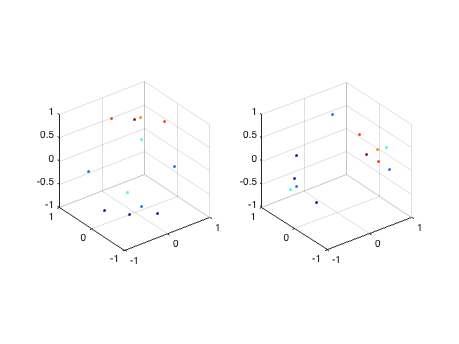

 figure

 subplot(1,2,1)
 scatter3(data(1,:),data(2,:),data(3,:),7,data(3,:),'o', 'filled')
 xlim([-1 1]), ylim([-1 1]), zlim([-1 1])
 axis square
 subplot(1,2,2)
 colormap('jet')
 scatter3(hopf_map(1,:),hopf_map(2,:),hopf_map(3,:),7,data(3,:),'o','filled')
 xlim([-1 1]), ylim([-1 1]), zlim([-1 1])
 axis square

 
%  for j=1:3
%      subplot(2,3,j)
%      scatter3(data(1,:),data(2,:),data(3,:),25,data(j,:),'.')
%      subplot(2,3,3+j)
%      scatter(alpha,beta,25,data(j,:),'.')
%  end